# Explore expanding CPR training set via transduction

## Load stuff, preprocess

load('framesJun22Trn.mat');
TRK = 'f:\romain\transduce20170206\rf2dB_5exps_initUseFF_11000to13000_full.trk';
trk = load(TRK,'-mat');
LBL = 'f:\Dropbox\MultiViewFlyLegTracking\multiview labeling\romainJun22NewLabels.lbl';
lbl = load(LBL,'-mat');

lpos = lbl.labeledpos{1}([1:18 19+(1:18) 19*2+(1:18)],:,:);
[lpos,nRm] = RF.rmOutlierOcc(lpos,lbl.movieInfoAll(1,:),outlier_desc_jun2216);
fprintf(1,'Removed outliers:\n');

Removed outliers:


nRm

nRm =      0     7     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     2     0
     0     0     0
     0    19     0
     0     0     0
     0     0     0
    35     0     0
     0     0     0
     0    41     0
     0    41     0
     0     0     0
    42     0     0
    43     0     0

frmB_trk = 11e3:13e3;
nfrmTrkB = numel(frmB_trk);
frmB_gt = sort(frmJun22Trn_11to13e3.B);
ngtB = numel(frmB_gt);
frmB_ngt = setdiff(frmB_trk,frmB_gt);
trkpos = trk.pTrk(:,:,frmB_trk);
trkposF = trk.pTrkFull(:,:,:,frmB_trk);
lpos = lpos(18*2+1:end,:,frmB_trk);
szassert(trkpos,size(lpos));

dpos = sqrt(sum((trkpos-lpos).^2,2));
dpos = squeeze(dpos)';
szassert(dpos,[nfrmTrkB 18]);

tfgt = ismember(frmB_trk,frmB_gt);
tfngt = ismember(frmB_trk,frmB_ngt);
dpos(tfngt,:) = nan; % some frames may have labels that were not used in training
assert(nnz(isnan(dpos(tfgt,:)))==0);

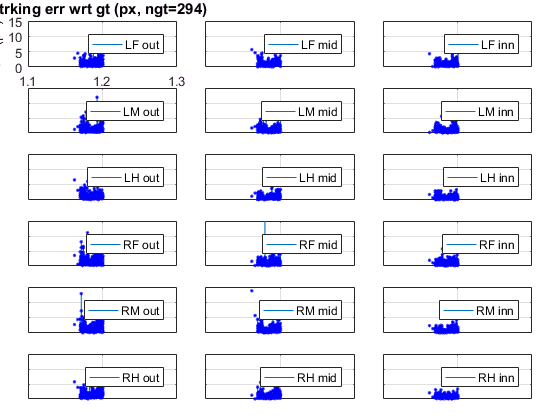

hFig = figure;
axs = createsubplots(6,3,.05);
axs = reshape(axs,[6 3]);
ptLegStrs = cell(18,1);
for ipt=1:18
  ax = axs(ipt);
  plot(ax,frmB_trk,dpos(:,ipt));
  hold(ax,'on')
  plot(ax,frmB_trk,dpos(:,ipt),'b.');
  grid(ax,'on');
  ax.XLim = [11e3 13e3];
  
  [r,c] = find(RF.PTMAP==ipt);
  legstr = [RF.PTMAPROWS{r} ' ' RF.PTMAPCOLS{c}];
  legend(ax,legstr);
  ptLegStrs{ipt} = legstr;
  if ipt==1
    %ax.XTickLabel = num2str(11e3:500:13e3);
  else
    ax.XTickLabel = [];
  end
  if ipt==1
    ylabel(ax,'err (px)')    
  else
    ax.YTickLabel = [];
  end
end
linkaxes(axs);
axs(1).YLim = [0 15];
tstr = sprintf('trking err wrt gt (px, ngt=%d)',ngtB);
title(axs(1),tstr,'fontweight','bold');
xlabel(axs(1),'frame','fontweight','bold');

## Boxplot dpos

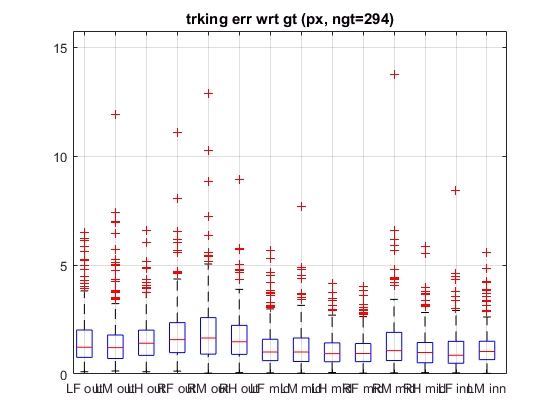

hFig = figure;
ax = axes;
boxplot(dpos,'labels',ptLegStrs);
grid(ax,'on');
ax.YLim = [0 20];
title(ax,tstr,'fontweight','bold');

## View outliers large dpos

if 0
  
dposSortRev = sort(dpos(~isnan(dpos)),'descend');
dposSortRev = dposSortRev(2:end); % get rid of first el, 111 outlier mislabeled pt 10
for i=1:20
  dposval = dposSortRev(i);
  [iF,ipt] = find(dpos==dposval);
  %lObj.setFrameGUI(frmB_trk(iF));
  
  input(sprintf('frm/pt: %d/%d, dposval = %.3f\n',frmB_trk(iF),ipt,dposval));
end

end

## Replicate Spreads

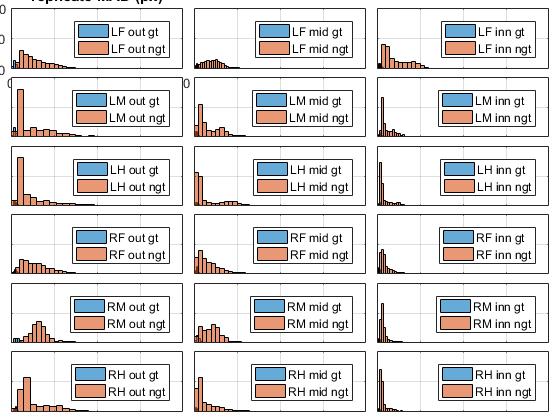

[trkposFVdmuRms,trkposFmad] = lclReplicateDmuRms(trkposF);

hFig = figure;
axs = createsubplots(6,3);
for ipt=1:18
  ax = axs(ipt);
  axes(ax);
  h(1) = histogram(trkposFmad(tfgt,ipt));
  hold(ax,'on');
  h(2) = histogram(trkposFmad(~tfgt,ipt));  
  grid(ax,'on');
  legend(ax,{[ptLegStrs{ipt} ' gt'],[ptLegStrs{ipt} ' ngt']});
  if ipt==1
    title(ax,'replicate MAD (px)','fontweight','bold');
  else
    ax.XTickLabel = [];
    ax.YTickLabel = [];
  end
end
linkaxes(axs);

ptileTrkPosFmadGT = prctile(trkposFmad(tfgt,:),[50 75 90 95 99])

ptileTrkPosFmadGT =    1.7391819   1.6265244   1.9746360   2.2346487   2.9585164   2.3417473   1.4691453   1.2364626   1.3070331   1.2703341   1.6729515   1.3388182   1.2720793   1.4651978   1.1901004   1.1525100   1.1501367   1.0367908
   2.4356647   2.3885038   2.6579041   2.9189076   3.8998289   2.9278488   2.0251942   1.9678345   1.7276208   1.7289950   2.4004691   1.8005425   1.8651582   1.8415174   1.4560214   1.4193261   1.5425845   1.2612865
   3.9094727   4.4671192   3.3474455   4.1270471   5.2233725   3.9596853   3.1018431   3.2447059   2.1455657   2.1722760   3.9134083   2.2216225   2.4764333   2.3735418   1.7679758   1.7759478   1.8806947   1.4734143
   6.1676707   7.9926500   3.8993721   4.6174407   7.2926712   4.6228199   4.1363168   4.5059013   2.2957542   2.5275948   5.5983915   2.7567365   2.7408376   2.5978694   2.0893278   2.0653031   2.1514828   1.7327766
   8.4484768  11.8980103   5.1880665   8.1481581  10.4890137   7.5357494   6.9972534   6.6665468   2.7544885   4

ptileTrkPosFmadNGT = prctile(trkposFmad(~tfgt,:),[1 5 10 30 50])

ptileTrkPosFmadNGT =    2.2832708   2.0729785   1.8652132   1.7632563   3.1262569   2.2824383   1.8582954   1.1974732   0.9804560   1.0946343   1.4322383   1.1506003   1.9281378   1.4636319   1.0384728   0.9182887   0.9984516   0.9854409
   3.6808629   3.0095634   2.9560311   3.5364485   6.7069511   3.2851593   2.7943521   1.5872668   1.3307993   1.3934921   1.8487275   1.5376624   2.5221074   1.9216027   1.3365438   1.2289125   1.3636346   1.2524059
   4.2945728   3.3945074   3.4568291   4.4814978   8.2142305   4.0583625   3.6624300   1.9369453   1.5479865   1.6875004   2.5597944   1.7042096   2.8985124   2.1081843   1.4822462   1.4564583   1.6073129   1.4324872
   6.6079311   4.2398214   4.5687528   7.1405473  11.2262173   6.3918996   6.6069679   3.1299303   1.9414757   3.0817003   5.1601424   2.1433170   4.3901396   2.5988355   1.7983431   2.3460951   2.1759758   1.8160871
   9.7439890   5.6352119   5.6511106  10.8873711  13.2800274   7.8905544   9.1058407   4.6698618   2.4353485   

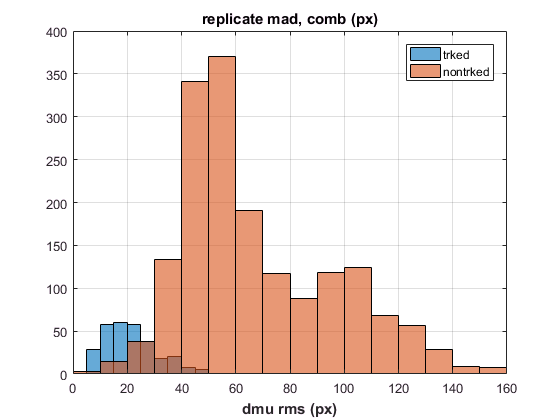



% trkposFVvol = nan(nfrmTrkB,1);
% for i=1:nfrmTrkB
%   x = trkposFV(:,:,i)';
%   szassert(x,[nrep 36]);
%   trkposFVvol(i) = sqrt(det(cov(x)));
% end

figure;
h(1) = histogram(trkposFVdmuRms(tfgt,:));
hold on;
h(2) = histogram(trkposFVdmuRms(~tfgt,:));
grid on;
title('replicate mad, comb (px)','fontweight','bold');
xlabel('dmu rms (px)','fontweight','bold');
legend(h,{'trked' 'nontrked'});


ptileDmuRmsGT = prctile(trkposFVdmuRms(tfgt,:),[50 75 90 95 99])

ptileDmuRmsGT =   20.0247498  26.5533066  35.8133774  38.9593277  47.6031494

ptileDmuRmsNGT = prctile(trkposFVdmuRms(~tfgt,:),[1 5 10 25 50])

ptileDmuRmsNGT =   19.5831642  32.8926125  39.2010880  47.5122643  58.8412132

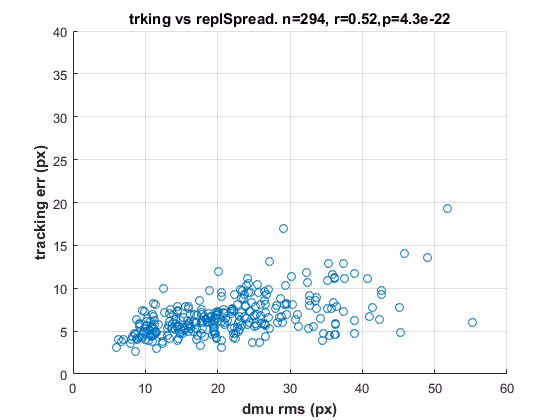


% correlation with gterr
dposComb = sqrt(sum(dpos.^2,2));
ngt = nnz(tfgt);
figure;
x = trkposFVdmuRms(tfgt,:);
y = dposComb(tfgt,:);
scatter(x,y);
grid on;
xlabel('dmu rms (px)','fontweight','bold');
ylabel('tracking err (px)','fontweight','bold');
tfOut = y>60;
xNoOut = x(~tfOut);
yNoOut = y(~tfOut);
[r,p] = corrcoef(xNoOut,yNoOut);
title(sprintf('trking vs replSpread. n=%d, r=%.2f,p=%.2g',ngt,r(1,2),p(1,2)),...
  'fontweight','bold');
ax = gca;
ax.XLim = [0 60];
ax.YLim = [0 40];

## Frame-to-Frame dists

% get tables of 2 consecutive frames
frm2 = nan(0,1); % second frame in consecutive seq
frm2off = nan(0,1); % frame offset (frm2-11e3+1)
p1 = nan(0,36); % coords at t-1 (all x, then all y)
p2 = nan(0,36); % coords at t
d12 = nan(0,1); % RMS eqdist between p1 and p2 (mean over 18 pts)

for i=2:ngtB
  f2 = frmB_gt(i);
  f2Off = f2-11e3+1;
  tfConsec = (frmB_gt(i-1)==f2-1);
  if tfConsec
    frm2(end+1,1) = f2;
    frm2off(end+1,1) = f2Off;
    tmp = lpos(:,:,f2Off);
    p1(end+1,:) = tmp(:)';
    tmp = lpos(:,:,f2Off-1);
    p2(end+1,:) = tmp(:)';
    d12(end+1,1) = sqrt(sum((p1(end,:)-p2(end,:)).^2,2)/18);
  end
end

tblConsec2 = table(frm2,frm2off,p1,p2,d12);

figure
histogram(tblConsec2.d12)
title('dist btwn consec lbled frms (px)','fontweight','bold');
grid on;

## velpred

- Find 3 consecutive labeled frames. 

- Find pts that have labels in all 3 frames. CURRENTLY ONLY LOOKIN WHEN ALL 3 LABELED PTS ARE DIFFERENT. - How good are i) vel, ii) damp*vel, iii) orig at predicting pos in 3rd frame?

DAMPS = 0:.05:1;
nDamps = numel(DAMPS);
  
frm3 = nan(0,1); % third frame in consecutive seq
frm3Off = nan(0,1); % frm3-11e3+1
ipts = nan(0,1); % point index
pAct = nan(0,2); % labeled [x y] of pt
pPrv = nan(0,2); % previous labeled [x y]
pPrdD = cell(0,1); % predicted based on pAct, pPrv, dampvel. each el is [nDampsx2]
ePrv = nan(0,1);
ePrdD = cell(0,1);
pTrk = nan(0,2); % tracked [x y] of pt
eTrk = nan(0,1); 
for i=3:ngtB
  f3 = frmB_gt(i);  
  tfConsec = isequal(frmB_gt(i-2:i),(f3-2:f3)');
  if tfConsec
    f3Off = f3-11e3+1;    
    p123 = lpos(:,:,f3Off-2:f3Off);
    for iPt = 1:18
      p = p123(iPt,:,:);
      p = squeeze(p)';
      szassert(p,[3 2]); % rows: [f1 f2 f3]. cols: [x y]
      if nnz(isnan(p)|isinf(p))==0 && size(unique(p,'rows'),1)==3
        frm3(end+1,1) = f3;
        frm3Off(end+1,1) = f3Off;
        ipts(end+1,1) = iPt;
        pAct(end+1,:) = p(3,:);
        pPrv(end+1,:) = p(2,:);
        ePrv(end+1,1) = sqrt(sum((p(3,:)-p(2,:)).^2));
        tmp = arrayfun(@(x)p(2,:)+x*(p(2,:)-p(1,:)),DAMPS,'uni',0);
        pPrdDthis = cat(1,tmp{:});
        pPrdD{end+1,1} = pPrdDthis;
        szassert(pPrdDthis,[nDamps 2]);
        ePrdD{end+1,1} = sqrt(sum((p(3,:)-pPrdDthis).^2,2));
        
        pTrkf3 = trkpos(iPt,:,f3Off);
        pTrk(end+1,:) = pTrkf3;
        eTrk(end+1,1) = sqrt(sum((p(3,:)-pTrkf3).^2));
      end
    end
  end
end
tblConsec3 = table(frm3,frm3Off,ipts,pAct,pPrv,pPrdD,ePrv,ePrdD,pTrk,eTrk);

%
npts = 18;
errPrvMu = nan(nDamps,npts);
errPrvMdn = nan(nDamps,npts);
errPrdDMu = nan(nDamps,npts);
errPrdDMdn = nan(nDamps,npts);
for iDamp=1:nDamps
  for iPt=1:npts
    tf = tblConsec3.ipts==iPt;
    
    pActThis = tblConsec3.pAct(tf,:);
    pPrvThis = tblConsec3.pPrv(tf,:);
    pPrdDThis = tblConsec3.pPrdD(tf,:);
    pPrdDThis = cellfun(@(x)x(iDamp,:),pPrdDThis,'uni',0);
    pPrdDThis = cat(1,pPrdDThis{:});
    
    ePrvThis = sqrt(sum((pActThis-pPrvThis).^2,2));
    ePrdDThis = sqrt(sum((pActThis-pPrdDThis).^2,2));        
    errPrvMu(iDamp,iPt) = mean(ePrvThis);
    errPrvMdn(iDamp,iPt) = median(ePrvThis);
    errPrdDMu(iDamp,iPt) = mean(ePrdDThis);
    errPrdDMdn(iDamp,iPt) = median(ePrdDThis);
  end
  fprintf(1,'Damp %d\n',iDamp);
end
errPrdDMuTot = sum(errPrdDMu,2);
errPrdDMdnTot = sum(errPrdDMdn,2);
errPrvMuTot = sum(errPrvMu,2);
errPrvMdnTot = sum(errPrvMdn,2);

%
LEGS = [ ...
  1 1 1;
  2 2 2;
  3 3 3;
  4 4 4;
  5 5 5;
  6 6 6];
LOCS = [  ...
  1 2 3;
  1 2 3;
  1 2 3;
  1 2 3;
  1 2 3;
  1 2 3];
LEGCOLORS = lines(6);
LOCMRKRS = {'.-' 's-' '^-'};

%
figure;
ax = createsubplots(1,4,.08); % rows: view. cols: [errPrvMu errPrdDMu errPrvMdn errPrdDMdn]
ax = reshape(ax,[1 4]);
arrayfun(@(x)hold(x,'on'),ax);
arrayfun(@(x)grid(x,'on'),ax);
for iVw=1
  hVw1 = gobjects(6,3);
  for iPt=1:18
    leg = LEGS(iPt);
    loc = LOCS(iPt);
    
    x = errPrvMu(:,iPt+(iVw-1)*18);
    szassert(x,[nDamps 1]);
    hVw1(iPt) = plot(ax(iVw,1),DAMPS(:),x,LOCMRKRS{loc},'Color',LEGCOLORS(leg,:));

    x = errPrdDMu(:,iPt+(iVw-1)*18);
    szassert(x,[nDamps 1]);
    plot(ax(iVw,2),DAMPS(:),x,LOCMRKRS{loc},'Color',LEGCOLORS(leg,:));

    x = errPrvMdn(:,iPt+(iVw-1)*18);
    szassert(x,[nDamps 1]);
    plot(ax(iVw,3),DAMPS(:),x,LOCMRKRS{loc},'Color',LEGCOLORS(leg,:));

    x = errPrdDMdn(:,iPt+(iVw-1)*18);
    szassert(x,[nDamps 1]);
    plot(ax(iVw,4),DAMPS(:),x,LOCMRKRS{loc},'Color',LEGCOLORS(leg,:));
  end
  if iVw==1
    hLeg = hVw1';
    hLeg = hLeg(:);
    strs = RF.PTNAMES';
    strs = strs(:);
    legend(ax(iVw,1),hLeg,strs);
    
    title(ax(iVw,1),'errPrvMu','fontweight','bold');
    title(ax(iVw,2),'errPrdDMu','fontweight','bold');
    title(ax(iVw,3),'errPrvMdn','fontweight','bold');
    title(ax(iVw,4),'errPrdDMdn','fontweight','bold');
    
    xlabel(ax(iVw,1),'dampfac','fontweight','bold');
    ylabel(ax(iVw,1),'error(px)','fontweight','bold');
    
    ax(iVw,2).XTickLabel = [];
    ax(iVw,2).YTickLabel = [];
    ax(iVw,4).XTickLabel = [];
    ax(iVw,4).YTickLabel = [];
  else
    for col=1:4
      ax(iVw,col).XTickLabel = [];
      ax(iVw,col).YTickLabel = [];
    end
  end
end
linkaxes(ax(:,1:2));
linkaxes(ax(:,3:4));
arrayfun(@(x)grid(x,'on'),ax);

figure;
ax = createsubplots(1,4,.08); % rows: view. cols: [errPrvMu errPrdDMu errPrvMdn errPrdDMdn]
ax = reshape(ax,[1 4]);
arrayfun(@(x)hold(x,'on'),ax);
arrayfun(@(x)grid(x,'on'),ax);

plot(ax(1),DAMPS(:),errPrvMuTot);
plot(ax(2),DAMPS(:),errPrdDMuTot);
plot(ax(3),DAMPS(:),errPrvMdnTot);
plot(ax(4),DAMPS(:),errPrdDMdnTot);

title(ax(1),'errPrvMuTot','fontweight','bold');
title(ax(2),'errPrdDMuTot','fontweight','bold');
title(ax(3),'errPrvMdnTot','fontweight','bold');
title(ax(4),'errPrdDMdnTot','fontweight','bold');
    
xlabel(ax(1),'dampfac','fontweight','bold');
ylabel(ax(1),'error(px)','fontweight','bold');
linkaxes(ax);

% CONCLUSION AL 20170207 looking at Jun22 11e3->13e3: dampfac=0.4

## Pick a dampfac, focus on it

DAMPFAC = 0.4;
iDampUse = find(DAMPS==DAMPFAC)

errPrdDPts = cell(npts,1); % el i contains vector of observed errPrdD on gt data for pt i
errPrdDPtsImprov = cell(npts,1); % el i contains vector of observed errPrdD-errPrv on gt data for pt i
for ipt=1:npts
  tf = ipt==tblConsec3.ipts;
  errPrdDPts{ipt} = cellfun(@(x)x(iDampUse,:),tblConsec3.ePrdD(tf));
  errPrdDPtsImprov{ipt} = tblConsec3.ePrv(tf)-errPrdDPts{ipt};
end

% plot hists of errPrdDPts/improvement
figure;
axs = createsubplots(6,3,.05);
clear h;
for ipt=1:18
  axes(axs(ipt));
  h(1) = histogram(errPrdDPts{ipt});
%   hold on;
%   h(2) = histogram(errPrdDPtsImprov{ipt});
  grid on;
%   legend(h,{[RF.PTNAMES{ipt} ' errPrd'],[RF.PTNAMES{ipt} ' errPrdImprov']});
  legend(h,RF.PTNAMES{ipt});
  if ipt==1
    xlabel('errPrd (px)','fontweight','bold');
  end
end
linkaxes(axs);
axs(1).XLim = [0 80];

ptile50ErrPrdPts = cellfun(@(x)prctile(x,50),errPrdDPts)

% correlation between ePrd and ePrv
ePrd = cellfun(@(x)x(iDampUse,:),tblConsec3.ePrdD);
figure;
scatter(tblConsec3.ePrv,ePrd);
grid on;
xlabel('err prev, px','fontweight','bold');
ystr = sprintf('err pred (px, damp=%.2f)',DAMPFAC);
ylabel(ystr,'fontweight','bold');
[r,p] = corrcoef(tblConsec3.ePrv,ePrd);
tstr = sprintf('velpred err tracks eprv, r=%.3f,p=%.2g',r(1,2),p(1,2));
title(tstr,'fontweight','bold');

% correlation between errPrdDPts and 
figure;
axs = createsubplots(1,2,.1);
axes(axs(1));
x = ePrd;
y = tblConsec3.eTrk;
[r,p] = corrcoef(x,y);
scatter(x,y);
grid on;
xstr = sprintf('err pred (px, damp=%.2f)',DAMPFAC);
xlabel(xstr,'fontweight','bold');
ylabel('err trk, px','fontweight','bold');
tstr = sprintf('trkerr weakly corr w velpred, r=%.3f,p=%.2g',r(1,2),p(1,2));
title(tstr,'fontweight','bold');
set(gca,'XLim',[0 80],'YLim',[0 20]);
axes(axs(2));
scatter(x,y);
grid on;
set(gca,'XScale','log','YScale','log');

## Find/browse conf tracked frames.

% -- A conf tracked frame is: 
% -- 1. Adjacent/contiguous to previously accepted frames
% -- SKIP, this is similar to velpred criterion 2. Has <= a certain percentile of distance to adjacent previously accepted frame
% -- 3. Has <= a certain percentile of tot replicate dispersion
REPL_DMURMS = 39.2; % AL20170208 ~95%tile of gt dmuRms; best ~10%tile of nongt dmuRms
% -- 3a. Has <= a certain percentile of repl dispersion for each pt
REPL_DMURMS_PT = load('ptile30DmuRmsPtsNGT_20170208.mat');
REPL_DMURMS_PT = REPL_DMURMS_PT.ptile30DmuRmsPtsNGT; % 30%tile of dmuRmsNGT for each pt
szassert(REPL_DMURMS_PT,[18 1]);
% -- 4. Has <= a certain percentile of vel pred
VELPREDINFO = load('ptile50ErrPrdPts_20170208.mat');
DAMPFAC = VELPREDINFO.DAMPFAC

DAMPFAC =    0.400000000000000

ERRPRDPTS_50PTILE = VELPREDINFO.ptile50ErrPrdPts;
szassert(ERRPRDPTS_50PTILE,[18 1]);

frmsTrn = frmB_gt;
frmsTrnPrev = zeros(0,1);
while ~isequal(frmsTrn,frmsTrnPrev)
  frmsCand = unique([frmsTrn;frmsTrn+1;frmsTrn-1]);
  frmsCand = setdiff(frmsCand,frmsTrn);
  nCand = numel(frmsCand);
  fprintf('\n');
  fprintf('Start: %d frmsTrn, %d candidates.\n',numel(frmsTrn),nCand);
  fprintf('Cands: %s\n',mat2str(frmsCand));
  
  % Stage: ensure leading or trailing two frames are in frmsTrn for velPred
  assert(iscolumn(frmsCand));
  tfOK = false(nCand,1);
  for iCand = nCand:-1:1
    fCand = frmsCand(iCand);
    tfOK(iCand) = all(ismember([fCand-1;fCand-2],frmsTrn)) || ...
                  all(ismember([fCand+1;fCand+2],frmsTrn));
  end
  frmsFail = frmsCand(~tfOK);
  frmsCand = frmsCand(tfOK);
  nCand = numel(frmsCand);
  fprintf('Stage, two neighbors: %d candidates remain.\n',nCand);
  fprintf('Failed: %s\n',mat2str(frmsFail));  
    
  % Stage: replicate dispersion, total and per-pt
  frmsCandOffset = frmsCand-11e3+1;  
  trkposFCand = trkposF(:,:,:,frmsCandOffset);  
  szassert(trkposFCand,[18 2 nrep nCand]);
  [dmuRmsCand,madPtCand] = lclReplicateDmuRms(trkposFCand);
  
  tfCombOK = dmuRmsCand <= REPL_DMURMS;
  tfPtsOK = all(madPtCand<=REPL_DMURMS_PT',2);
  nCombNOK = nnz(~tfCombOK);
  nPtsNOK = nnz(~tfPtsOK);
  tfOK = tfCombOK & tfPtsOK;
  
  frmsFail = frmsCand(~tfOK);
  frmsCand = frmsCand(tfOK);
  nCand = numel(frmsCand);
  fprintf('Stage, repl: %d candidates remain (%d/%d failed tot/per-pt disperion).\n',nCand,nCombNOK,nPtsNOK)
  fprintf('Failed: %s\n',mat2str(frmsFail));  

  % Stage: velpred
  [flag,pCandPred] = lclVelPred(frmsCand,lpos,frmB_trk,DAMPFAC);
  szassert(pCandPred,[18 2 nCand]);
  tfOK = false(nCand,1);
  for iCand=1:nCand
    if flag(iCand)==0
      continue;
    end
    
    fCand = frmsCand(iCand);
    fCandOff = fCand-11e3+1;
    
    pTrk = trkpos(:,:,fCandOff);
    pPrd = pCandPred(:,:,iCand);
    errPrd = sqrt(sum((pTrk-pPrd).^2,2));
    
    tfOK(iCand) = all(errPrd<=ERRPRDPTS_50PTILE);
  end
  frmsFail = frmsCand(~tfOK);
  frmsCand = frmsCand(tfOK);
  nCand = numel(frmsCand);
  fprintf('Stage, velpred: %d candidates remain.\n',nCand)
  fprintf('Failed: %s\n',mat2str(frmsFail));  
  
  frmsTrnPrev = frmsTrn;
  frmsTrn = union(frmsTrn,frmsCand);
end

Start: 294 frmsTrn, 21 candidates.


Cands: [11623;11625;11667;11669;11699;11784;11786;11788;11789;11792;11823;11832;11833;11835;11836;11841;11851;11853;11856;11901;12009]


Stage, two neighbors: 12 candidates remain.


Failed: [11623;11625;11667;11669;11786;11788;11833;11835;11853]


Stage, repl: 7 candidates remain (0/5 failed tot/per-pt disperion).


Failed: [11699;11832;11841;11901;12009]


Stage, velpred: 3 candidates remain.


Failed: [11784;11789;11792;11823]


Start: 297 frmsTrn, 19 candidates.


Cands: [11623;11625;11667;11669;11699;11784;11786;11788;11789;11792;11823;11832;11833;11835;11841;11853;11855;11901;12009]


Stage, two neighbors: 12 candidates remain.


Failed: [11623;11625;11667;11669;11786;11788;11833]


Stage, repl: 7 candidates remain (0/5 failed tot/per-pt disperion).


Failed: [11699;11832;11841;11901;12009]


Stage, velpred: 3 candidates remain.


Failed: [11784;11789;11792;11823]


Start: 300 frmsTrn, 17 candidates.


Cands: [11623;11625;11667;11669;11699;11784;11786;11788;11789;11792;11823;11832;11833;11841;11854;11901;12009]


Stage, two neighbors: 11 candidates remain.


Failed: [11623;11625;11667;11669;11786;11788]


Stage, repl: 6 candidates remain (0/5 failed tot/per-pt disperion).


Failed: [11699;11832;11841;11901;12009]


Stage, velpred: 0 candidates remain.


Failed: [11784;11789;11792;11823;11833;11854]



frmsTrnNew = setdiff(frmsTrn,frmB_gt);
fprintf('DONE. %d new trn frames: %s\n',numel(frmsTrnNew),mat2str(frmsTrnNew));

DONE. 6 new trn frames: [11835;11836;11851;11853;11855;11856]


% hLine = RF.add...
frm = lObj.currFrame;
frmOff = frm-11e3+1;
tposF = trkposF(:,:,:,frmOff);
for ipt=1:18
    set(hLine(ipt),'XData',squeeze(tposF(ipt,1,:)),...
                   'YData',squeeze(tposF(ipt,2,:)));
end

frms = [11699;11700];
[dmuRms,madPt] = lclReplicateDmuRms(trkposF(:,:,:,frms-11e3+1));

function [flag,pPred] = lclVelPred(frmsPred,lpos,lposFrms,damp)
  %
  % frmsPred: [n], vector of frame numbers to predict
  % lpos: [18x2xN], labels
  % lposFrms: [N], frames labeling 3rd dim of lpos. Note, frmsPred and lposFrms can be either absolute
  %     or relative/offset frames, as long as they are consistent.
  % damp: [1]. velocity damping factor.
  %
  % flag: [n], either {0,-1,1} for not-predicted, backward-predicted, forward-predicted
  % pPred: [18x2xn], predicted shapes for frames frmsPred.
  %
  % frmsPred must be adjacent to two consecutive frames in lposFrms and is generated either linear
  % extrapolation (with damping) either forwards or backwards in time as appropriate.
  
  assert(isvector(frmsPred));
  n = numel(frmsPred);
  N = size(lpos,3);
  szassert(lpos,[18 2 N]);
  assert(isvector(lposFrms) && numel(lposFrms)==N);
  assert(isscalar(damp));
  
  pPred = nan(18,2,n);
  flag = zeros(n,1);
  for i=1:n
    fPred = frmsPred(i);
    fPredNbrs = fPred + [-2;-1;1;2];
    [tf,loc] = ismember(fPredNbrs,lposFrms);
    if all(tf(1:2))
      ptm2 = lpos(:,:,loc(1));
      ptm1 = lpos(:,:,loc(2));
      pdel = ptm1-ptm2;
      pPred(:,:,i) = ptm1+damp*pdel;
      flag(i) = 1;
    elseif all(tf(3:4))
      ptp1 = lpos(:,:,loc(3));
      ptp2 = lpos(:,:,loc(4));
      pdel = ptp2-ptp1;
      pPred(:,:,i) = ptp1-damp*pdel;
      flag(i) = -1;
    else
      % no adjacent labeled frames; no-op, flag(i) already 0
    end
  end
end

function [dmuRms,madPt] = lclReplicateDmuRms(trkposF)
  % dmuRms: [nfrm 1]. sqrt(sq-eq dist from replicate mediod (combining all pts into giant vec), averaged across reps)
  % madPt: [nfrm 18]. mad (median dev from replicate mediod) for each pt, frm
  
  [npt,d,nrep,nfrm] = size(trkposF);
  assert(npt==18);
  assert(d==2);
  
  trkposFV = reshape(trkposF,[36 nrep nfrm]);
  trkposFVmdod = median(trkposFV,2); % replicate-mediod
  trkposFVdmu2 = sum((trkposFV-trkposFVmdod).^2,1); % [1xnrepxnfrm] sq-eq dist for each rep from rep-mediod
  trkposFVdmuRms = sqrt(sum(trkposFVdmu2,2)/nrep); % [1x1xnfrm]  sqrt(sq-eq dist from mediod, averaged across reps)
  szassert(trkposFVdmuRms,[1 1 nfrm]);
  dmuRms = trkposFVdmuRms(:);
  
  trkposFmdod = median(trkposF,3,'includenan'); % shouldn't be any nans
  szassert(trkposFmdod,[18 2 1 nfrm]);
  trkposFdmdn = sqrt(sum((trkposF-trkposFmdod).^2,2)); % eq dist to replicate-mediod for each pt, rep, frm
  szassert(trkposFdmdn,[18 1 nrep nfrm]);
  madPt = squeeze(median(trkposFdmdn,3,'includenan'));
  szassert(madPt,[18 nfrm]);
  madPt = madPt';
end
